f=@(x) cos(1.5*pi*x);
points = 3;
X = linspace(0,1,points);
df = derivate(f);
Y = f(X);
P = polyfit(X,Y,points-1);
XX = linspace(X(1),X(end),100);
disp("polyfit")

polyfit


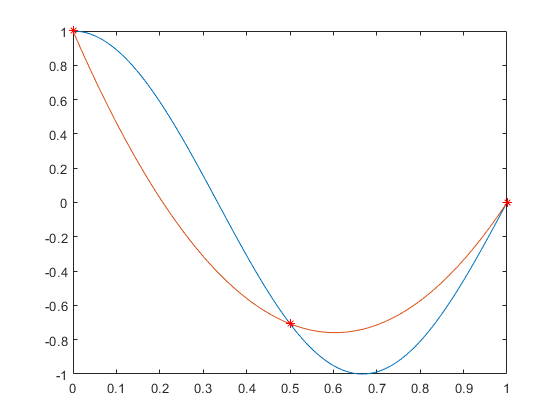

plot(XX,f(XX),XX,polyval(P,XX),X,Y,"r*")


YY_spline = spline(X,Y,XX);
disp("spline")

spline


plot(XX,f(XX),XX,YY_spline,X,Y,"r*")


YY_spline = spline(X,[df(X(1)) Y df(X(end))],XX);
disp("spline - with specified endpoint slopes")

spline - with specified endpoint slopes


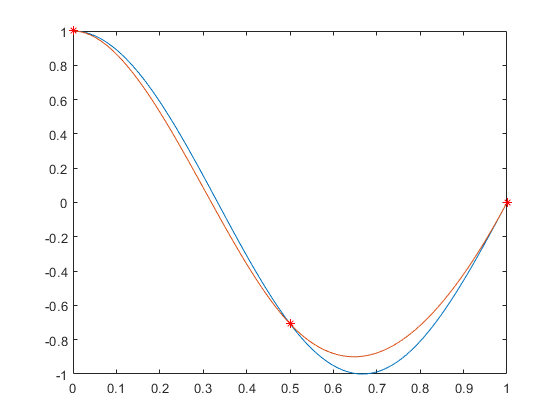

plot(XX,f(XX),XX,YY_spline,X,Y,"r*")


syms t
f_bern = matlabFunction(bernstein(f,points-1,t));
disp("bernstein")

bernstein


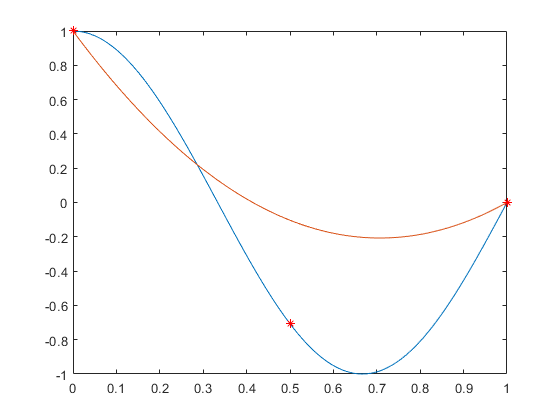

plot(XX,f(XX),XX,f_bern(XX),X,Y,"r*")